## MA431 - Project 2 - No Friction

clc; clear all; close all;

g = 9.81;
L = 2.015;
s_0 = 0.82;

syms t
eq = L == s_0/2 * exp(sqrt(g/L) * t) + s_0/2 * exp(-sqrt(g/L) * t)

$$eq = \frac{403}{200}=\frac{41\,{\mathrm{e}}^{-\frac{3\,\sqrt{218}\,\sqrt{403}\,t}{403}}}{100}+\frac{41\,{\mathrm{e}}^{\frac{3\,\sqrt{218}\,\sqrt{403}\,t}{403}}}{100}$$

t = vpa(solve(eq,t))

$$t = \left(\begin{array}{c} -0.70156516309310705498271881668633\\ 0.70156516309310705498271881668633 \end{array}\right)$$


t1 = 0;
idx = 1;
dt = 10^-3;
s = 0;
while s <= L
s = s_0/2 * exp(sqrt(g/L) * t1) + s_0/2 * exp(-sqrt(g/L) * t1);
t_plot(idx) = t1;
s_plot(idx) = s;
t1 = t1 + dt;
idx = idx + 1;
end

fig = figure;
plot(t_plot, s_plot, 'k','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
%hold on
grid on
legend("Length of s", 'interpreter','latex')
title("Analytical Approach Without Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "analytical_solution_without_friction_chain_problem.eps"

filename = "analytical_solution_without_friction_chain_problem.eps"

saveas(fig,filename, 'epsc')

## Numerical approach, frictionless

simTime = 3; % s
t = 0; % Start time
idx = 1; % Index for logging
dt = 10^-4; % Time step

%L = 3; % Complete length of the chain
%s_0 = 1; % Length of the chain that is hanging of the table

% I.C
s = s_0; % s(0) = 1 m (1 m of the chain is hanging of the table
sDot = 0; % s'(0) = 0 m/s

% Calculation
while t < simTime

    sDotDot = (g/L) * s;

    % Save results for plotting
    timePlot(idx) = t;
    sPlot(idx) = s;
    sDotPlot(idx) = sDot;
    sDotDotPlot(idx) = sDotDot;

    % Time integrate y, yDot and update time, index variables
    s = s+sDot*dt;          % Position
    sDot = sDot+sDotDot*dt; % Velocity
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

x = timePlot(sPlot<=L);
tot_time = x(end)

tot_time =          0.701599999999939


## Numerical approach frictionless plot

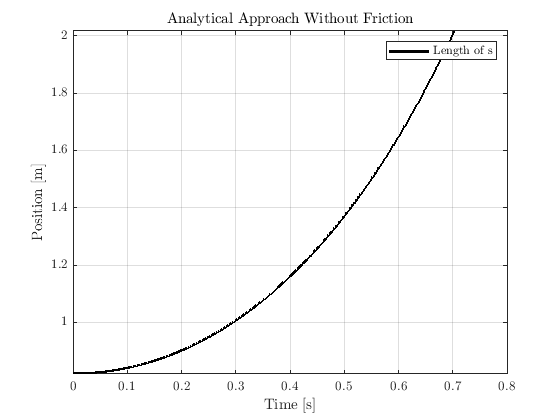

hold off

fig = figure;
plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'r','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
%hold on
%plot([0 3], [-2 -2])
grid on
legend("Length of s", 'interpreter','latex')
title("Numerical Approach Without Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "numerical_solution_without_friction_chain_problem.eps"

filename = "numerical_solution_without_friction_chain_problem.eps"

saveas(fig,filename, 'epsc')

## Analytical vs. Numerical approach frictionless plot

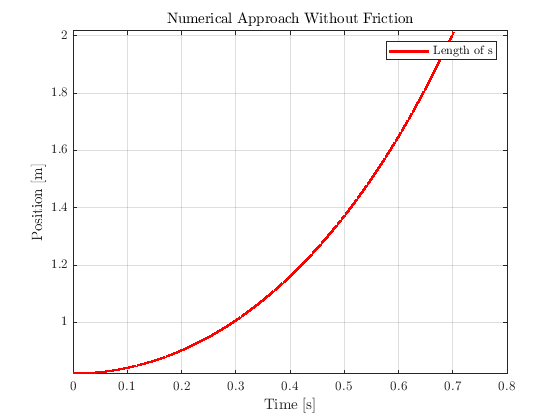

hold off

fig = figure;
plot(t_plot, s_plot, '--ok','LineWidth',2, 'MarkerIndices', 1:20:length(s_plot))
hold on
plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'r','LineWidth',2)
ylim([min(s_plot) max(s_plot)])
grid on
legend("Length of s, analytical", "Length of s, numerical", 'interpreter','latex')
title("Analytical vs. Numerical Approach Without Friction", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')
filename = "analytical_vs_numerical_solution_without_friction_chain_problem.eps"

filename = "analytical_vs_numerical_solution_without_friction_chain_problem.eps"

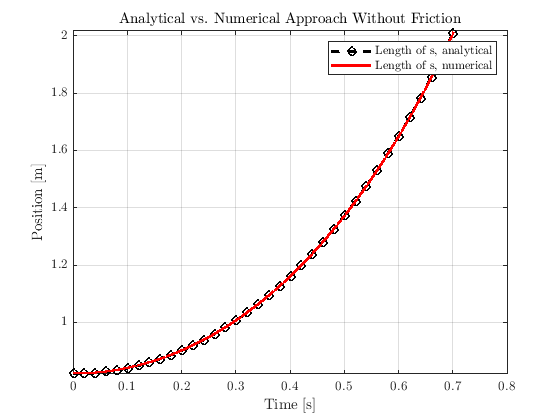

saveas(fig,filename, 'epsc')